# Neural network based control for nonlinear affine systems with input saturation

## Van der Pol Oscilator

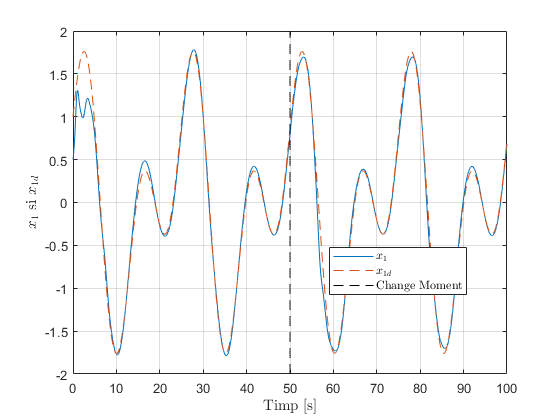

% simulation data
Ts = 0.01;
t = 0:Ts:100;
x0 = [0.5; 0.5];
zeta0 = [0; 0];
mu = 1;
input_upperbound = 2;
input_lowerbound = -2;

Ac = -eye(2); 
K = -eye(2);
h = [-10; -10];

% weight adaption parameters
lr = 0.7; % learining rate
gamma = 0.0001; % damping coefficient

% desired trajectory
xd = [sin(0.5*t) + cos(0.25*t); 0.5*cos(0.5*t) - 0.25*sin(0.25*t)];

% neural network parameters
input_size = 4;
hidden_layer_size = 20;
Vc = rands(hidden_layer_size, input_size);
Wc = rands(1, hidden_layer_size);

% state and input initialization
x = zeros(2, length(t));
zeta = zeros(2, length(t));
u = zeros(length(t), 1);
e = zeros(2, length(t));

x(:, 1) = x0;
zeta(:, 1) = zeta0;
delta_u = 0;

aux = floor(length(t)/2);

for i = 1:length(t) - 1
    if i == aux
        mu = mu + 1.2;
    end
    
    e(:, i) = x(:, i) - xd(:, i) - zeta(:, i);
    x_cnn = [e(:, i); xd(:, i)];
    
    % backpropagation
    dWc = e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u)*(-tanh(Vc*x_cnn))';
    dVc = (e(:, i)'*(-inv(Ac)*ones(2, 1) + inv(K)*h*delta_u)*(-Wc*diag(1 - tanh(Vc*x_cnn).^2)))'*x_cnn';
    
    Wc = Wc + Ts*(-lr*dWc - gamma*norm(e(:, i))*Wc - gamma*norm(zeta(:, i))*Wc);
    Vc = Vc + Ts*(-lr*dVc - gamma*norm(e(:, i))*Vc - gamma*norm(zeta(:, i))*Vc);
    
    u(i) = -Wc*tanh(Vc*x_cnn);
    [u(i), delta_u] = control_saturation(u(i), input_lowerbound, input_upperbound);
    
    x(:, i + 1) = x(:, i) + Ts*van_der_pol_derivatiave(x(:, i), u(i), mu);
    zeta(:, i + 1) = zeta(:, i) + Ts*aux_system_derivative(zeta(:, i), delta_u, K, h);
end

figure, 
plot(t, x(1, :)); hold on; grid;
plot(t, xd(1, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_1$ si $x_{1d}$", "Interpreter","latex");
legend("$x_1$", "$x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

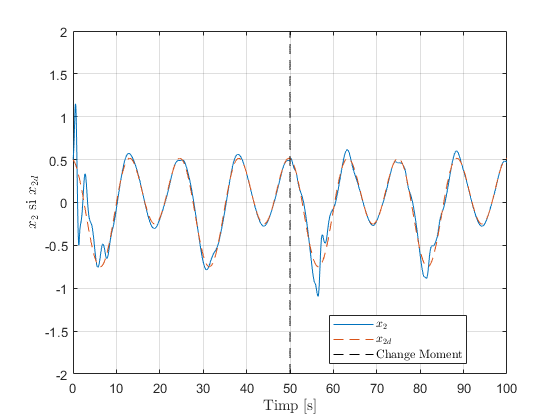


figure, 
plot(t, x(2, :)); hold on; grid;
plot(t, xd(2, :), "--");
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp [s]", "Interpreter","latex");
ylabel("$x_2$ si $x_{2d}$", "Interpreter","latex");
legend("$x_2$", "$x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

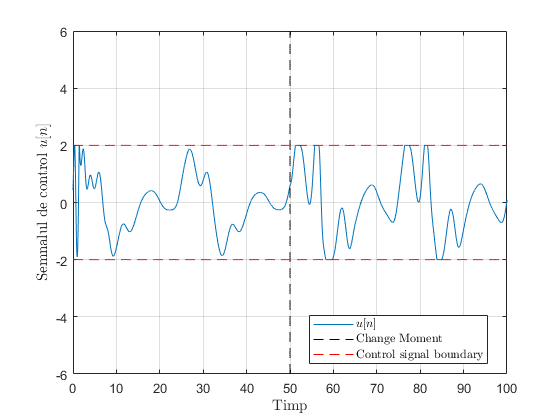


figure,
plot(t, u); grid; hold on;
plot(t(aux)*ones(length(t), 1), t*0.12 - 6, "Color", "Black", "LineStyle","--");
plot(t, input_upperbound*ones(size(t)), "Color", "Red", "LineStyle","--");
plot(t, input_lowerbound*ones(size(t)), "Color", "Red", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("Semnalul de control $u[n]$", "Interpreter","latex");
legend("$u[n]$", "Change Moment", "Control signal boundary",  "Interpreter", "Latex", "Location","best");

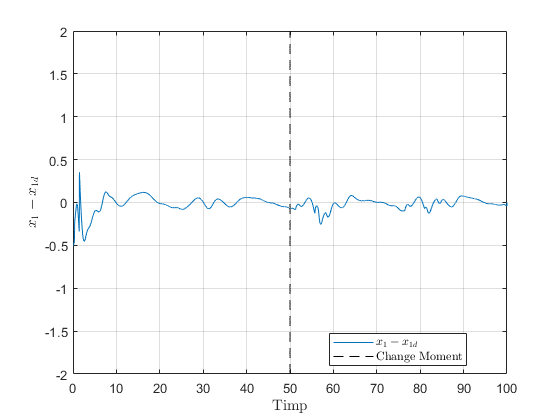


figure, 
plot(t, e(1, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_1 - x_{1d}$", "Interpreter","latex");
legend("$x_1 - x_{1d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

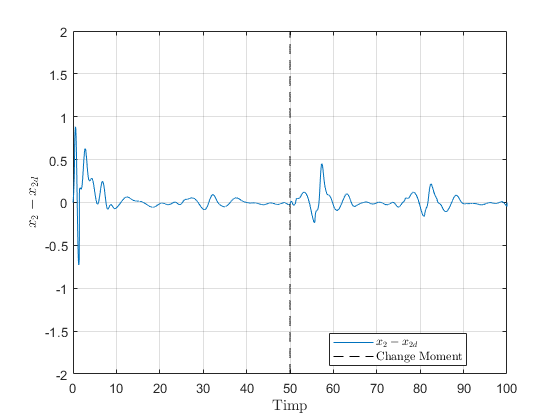


figure, 
plot(t, e(2, :)); grid; hold on;
plot(t(aux)*ones(length(t), 1), t/25 - 2, "Color", "Black", "LineStyle","--");
xlabel("Timp", "Interpreter","latex");
ylabel("$x_2 - x_{2d}$", "Interpreter","latex");
legend("$x_2 - x_{2d}$", "Change Moment", "Interpreter", "Latex", "Location","best");

function [u_saturated, delta_u] = control_saturation(u, lower_bound, upper_bound)
   if u < lower_bound
       u_saturated = lower_bound;
   else 
       if u > upper_bound
           u_saturated = upper_bound;
       else
           u_saturated = u;
       end
   end
   
   delta_u = u - u_saturated;
end

function dx = van_der_pol_derivatiave(x, u, mu)
    dx = [x(2);
          mu*(1 - x(1)^2)*x(2) - x(1) + u];
end

function dzeta = aux_system_derivative(zeta, delta_u, K, h)
    dzeta = K*zeta + h*delta_u;
end

function y = tanh(x)
    y = (exp(x) - exp(-x))./(exp(x) + exp(-x));
end